clear;clc;
open_system("rlBallandPlate")
numObs = 3;  % Number of dimension of the observation space
numAct = 3;   % Number of dimension of the action space

obsInfo = rlNumericSpec([numObs 1]);
 
actInfo = rlNumericSpec([numAct 1]);
actInfo.LowerLimit = -0;
actInfo.UpperLimit = 10;

Create the Simulink environment interface using the observation and action specifications. For more information on creating Simulink environments, see [`rlSimulinkEnv`](docid:rl_ref#mw_12cc40dc-3191-4a23-af71-1625696c1a14).

mdl = "rlBallandPlate";
blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

Specify a reset function for the environment using the `ResetFcn` parameter. 

env.ResetFcn = @kinovaResetFcn;

Specify the sample time `Ts` and simulation time `Tf`.

Ts = 0.1;
Tf = 20;

% Set the random seed for reproducibility.
rng(0)

% Define the network layers.
cnet = [
    featureInputLayer(numObs,Name="observation")
    fullyConnectedLayer(650)
    concatenationLayer(1,2,Name="concat")
    reluLayer
    fullyConnectedLayer(650)
    reluLayer
    fullyConnectedLayer(650)
    reluLayer
    fullyConnectedLayer(1,Name="CriticOutput")];
actionPath = [
    featureInputLayer(numAct,Name="action")
    fullyConnectedLayer(650,Name="fc2")];

% Connect the layers.
criticNetwork = layerGraph(cnet);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = connectLayers(criticNetwork,"fc2","concat/in2");

View the critic neural network.

%plot(criticNetwork)

When using two critics, a SAC agent requires them to have different initial parameters. Create and initialize two `dlnetwork` objects.

criticdlnet = dlnetwork(criticNetwork,'Initialize',false);
criticdlnet1 = initialize(criticdlnet);
criticdlnet2 = initialize(criticdlnet);

Create the critic functions using `rlQValueFunction`.

critic1 = rlQValueFunction(criticdlnet1,obsInfo,actInfo, ...
    ObservationInputNames="observation", ActionInputNames="action");
critic2 = rlQValueFunction(criticdlnet2,obsInfo,actInfo, ...
    ObservationInputNames="observation", ActionInputNames="action");

% Create the actor network layers.
commonPath = [
    featureInputLayer(numObs,Name="observation")
    fullyConnectedLayer(650)
    eluLayer
    fullyConnectedLayer(450)
    tanhLayer(Name="anet_out")];
meanPath = [
    fullyConnectedLayer(450,Name="meanFC")
    eluLayer(Name="relu3")
    fullyConnectedLayer(numAct,Name="mean")];
stdPath = [
    fullyConnectedLayer(numAct,Name="stdFC")
    eluLayer(Name="relu4")
    softplusLayer(Name="std")];

% Connect the layers.
actorNetwork = layerGraph(commonPath);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);
actorNetwork = connectLayers(actorNetwork,"anet_out","meanFC/in");
actorNetwork = connectLayers(actorNetwork,"anet_out","stdFC/in");

View the actor neural network.

actordlnet = dlnetwork(actorNetwork);
actor = rlContinuousGaussianActor(actordlnet, obsInfo, actInfo, ...
    ObservationInputNames="observation", ...
    ActionMeanOutputNames="mean", ...
    ActionStandardDeviationOutputNames="std");

agentOpts = rlSACAgentOptions( ...
    SampleTime=Ts, ...
    TargetSmoothFactor=5e-3, ...    
    ExperienceBufferLength=1e6, ...
    MiniBatchSize=256, ...
    NumWarmStartSteps=1000, ...
    DiscountFactor=0.99);

For this example the actor and critic neural networks are updated using the Adam algorithm with a learn rate of 1e-4 and gradient threshold of 1. Specify the optimizer parameters.

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 1e-4;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;

for ct = 1:2
    agentOpts.CriticOptimizerOptions(ct).Algorithm = "adam";
    agentOpts.CriticOptimizerOptions(ct).LearnRate = 1e-4;
    agentOpts.CriticOptimizerOptions(ct).GradientThreshold = 1;
end

Create the SAC agent.

agent = rlSACAgent(actor,[critic1,critic2],agentOpts);

trainOpts = rlTrainingOptions(...
    MaxEpisodes=150, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=250, ...
    Plots="training-progress", ...
    StopTrainingCriteria="EpisodeCount", ...
    StopTrainingValue=1000, ...
    UseParallel=false);

doTraining = true;
if doTraining
    %trainResult = train(agent,env,trainOpts,Logger=logger);
    trainResult = train(agent,env,trainOpts);
else
    %load("kinovaBallBalanceAgent.mat")       
end

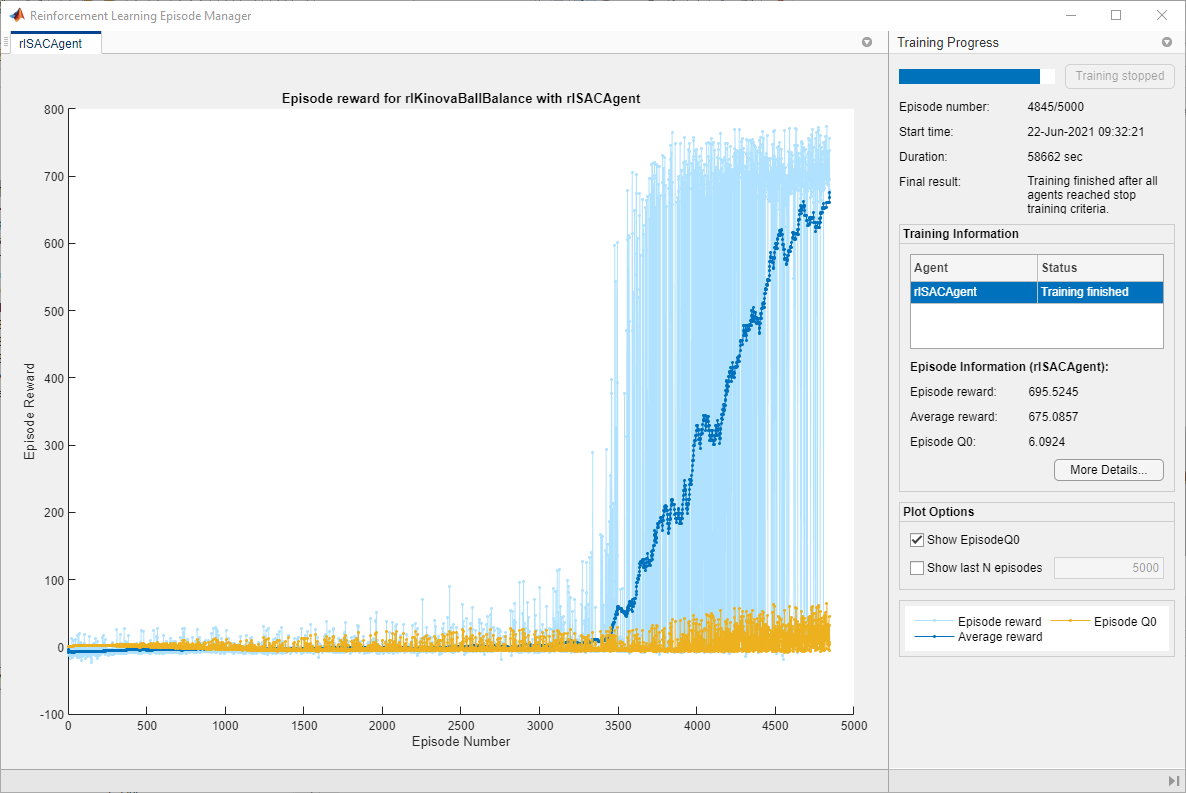

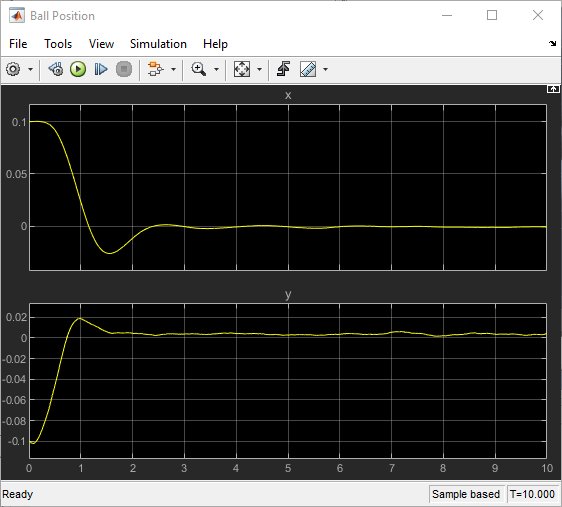

function in = kinovaResetFcn(in) 
% Reset function for PFC multi-agent RL example
% randomize reference signal
blk = sprintf('rlBallandPlate/Reference');
h = 1;
in = setBlockParameter(in,blk,'Value',num2str(h));

end